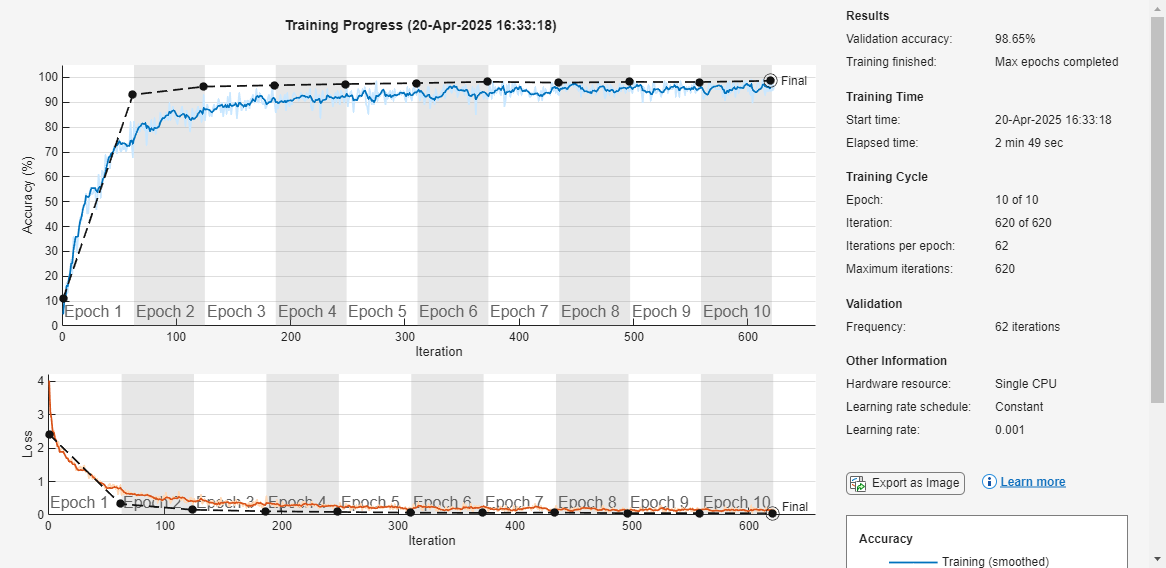

%% Clasificación de dígitos MNIST con una CNN mejorada

%% 1) Configuración inicial
clc; clear; close all;
rng(42);

%% 2) Carga de datos
load('digits.mat');        % digits.image (784×10000), digits.label (1×10000)
Xraw = digits.image;       % 784×N
Yraw = digits.label;       % 1×N
N = size(Xraw, 2);

%% 3) Reconstruir imágenes 28×28 y normalizar a [0,1]
X = zeros(28,28,1,N,'single');
for i = 1:N
    img = reshape(Xraw(:,i), 28, 28)';   % reshape + trasponer
    X(:,:,1,i) = single(img) / 255;      % => [0,1]
end

%% 4) Etiquetas categóricas con 10 clases fijas
Y = categorical(Yraw, 0:9);

%% 5) División train / test (80 % / 20 %)
idx    = randperm(N);
nTrain = round(0.8 * N);
trainIdx = idx(1:nTrain);
testIdx  = idx(nTrain+1:end);

XTrain = X(:,:,:,trainIdx);
YTrain = Y(trainIdx);
XTest  = X(:,:,:,testIdx);
YTest  = Y(testIdx);

%% 6) Data augmentation (opcional pero muy efectivo)
aug = imageDataAugmenter( ...
    'RandRotation',[-10 10], ...
    'RandXTranslation',[-3 3], ...
    'RandYTranslation',[-3 3]);
dsTrain = augmentedImageDatastore([28 28], XTrain, YTrain, ...
    'DataAugmentation', aug);
dsTest  = augmentedImageDatastore([28 28], XTest,  YTest);

%% 7) Definición de la CNN
layers = [
    imageInputLayer([28 28 1],'Name','input')
    
    convolution2dLayer(3,  16,'Padding','same','Name','conv_1')
    batchNormalizationLayer(  'Name','bn_1')
    reluLayer(                'Name','relu_1')
    maxPooling2dLayer(2,'Stride',2,'Name','pool_1')
    
    convolution2dLayer(3, 32,'Padding','same','Name','conv_2')
    batchNormalizationLayer(  'Name','bn_2')
    reluLayer(                'Name','relu_2')
    maxPooling2dLayer(2,'Stride',2,'Name','pool_2')
    
    convolution2dLayer(3, 64,'Padding','same','Name','conv_3')
    batchNormalizationLayer(  'Name','bn_3')
    reluLayer(                'Name','relu_3')
    maxPooling2dLayer(2,'Stride',2,'Name','pool_3')
    
    fullyConnectedLayer(128,   'Name','fc_1')
    reluLayer(                 'Name','relu_4')
    dropoutLayer(0.5,          'Name','dropout')
    
    fullyConnectedLayer(10,    'Name','fc_out')
    softmaxLayer(              'Name','softmax')
    classificationLayer(       'Name','classoutput')
];

%% 8) Opciones de entrenamiento con validación
options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'InitialLearnRate',1e-3, ...
    'MiniBatchSize',128, ...
    'Shuffle','every-epoch', ...
    'ValidationData',dsTest, ...
    'ValidationFrequency',floor(nTrain/128), ...
    'Plots','training-progress', ...
    'Verbose',false);

%% 9) Entrenamiento
net = trainNetwork(dsTrain, layers, options);


%% 10) Evaluación sobre test
YPred = classify(net, dsTest);
accuracy = mean(YPred == YTest');
fprintf('Accuracy CNN en test: %.2f%%\n', accuracy*100);

Accuracy CNN en test: 98.65%


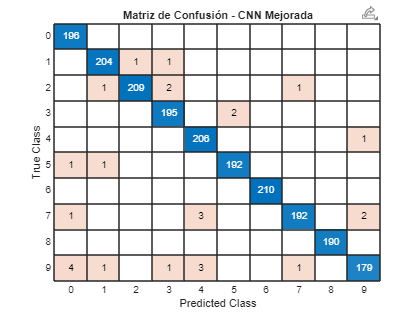

YPred = 2000×1 categorical array
     3 
     0 
     0 
     6 
     8 
     6 
     6 
     1 
     8 
     9 
     9 
     7 
     4 
     0 
     2 
     0 
     9 
     6 
     2 
     8 
     3 
     1 
     3 
     6 
     1 
     5 
     8 
     2 
     2 
     4 



%% 11) Matriz de confusión en test
figure;
confusionchart(YTest, YPred);
title('Matriz de Confusión - CNN Mejorada');